# Measuring Planar Objects with a Calibrated Camera

Measure the diameter of coins in world units using a single calibrated camera. The demonstration is a modified form of the MATLAB example available at [https://www.mathworks.com/help/vision/examples/measuring-planar-objects-with-a-calibrated-camera.html](https://www.mathworks.com/help/vision/examples/measuring-planar-objects-with-a-calibrated-camera.html) . 

## Overview

This example shows how to calibrate a camera, and then use it to measure position and the size of planar objects, such as coins. Camera calibration entails establishing parameters intrinsic to the camera in a pinhole camera model with distortions and assumes the camera has a fixed focal length. The calibration is valid only for that focal length so in what follows it is assumed that any autofocusing is disabled. A more elaborate model would encompass variable focus.

The camera is first used to take a number of images of a known object which is fixed in space, here a planar checkerboard. Each image of the checkerboard is a unique function of the position and orientation of the phone (6 degrees of freedom, 3 translation, 3 rotation collectively called extrinsic parameters) relative to world coordinates defined by the checkerboard and by a few (5) intrinsic parameters of the camera. Each image is analyzed to determine the relative location of the corners of the checkerboad squares supplying about one 2d coordinate pair per square. Four known points in a single image are sufficient to determine the extrinsic parameters if the intrinsic parameters are known. By using multiple views of a known object, the intrinsic parameters may be determined. This "calibration" may then be applied to determine the relative world coordinates of objects.

The algorithm is described at

[https://www.microsoft.com/en-us/research/publication/a-flexible-new-technique-for-camera-calibration/?](https://www.microsoft.com/en-us/research/publication/a-flexible-new-technique-for-camera-calibration/?)  .

Camera calibration is the process of estimating the parameters of the lens and the image sensor. These parameters are needed to measure objects captured by the camera. This example shows how to calibrate a camera programmatically. Alternatively, you can calibrate a camera using the `cameraCalibrator` app.

To calibrate the camera, we first need to take multiple images of a calibration pattern from different angles. A typical calibration pattern is an asymmetric checkerboard, where one side contains an even number of squares, both black and white, and the other contains an odd number of squares. The even and odd requirement facilitates detection of the orientation of the pattern in multiple views.

The pattern must be affixed to a flat surface, and it should be at approximately the same distance from the camera as the objects you want to measure. It defines a set of world coordinates with x-y in the plane and z normal to the plane. The size of a square must be measured in world units, for example millimeters, as precisely as possible. It is recommended to use 10 to 20 images for accurate calibration. Remember to fix the focal length, one of the intrinsic parameters to be determined. Note that an image that is a translation of another without rotation provides no new information (See reference above.). Also note that at with a fixed focal length, the camera will make sharp images over a limited range of depth. The feature detection step (finding the corners of the squares) will fail for blurry images so take your images over a limited range of distances and angles. 

You will have to experiment to discover which images are useful or not. It is suggested you use the Camera Calibration app to rapidly sift through your images to determine which are reconstructable and only apply this example code to the reconstructable set.

The workflow in the code is to first detect the square corners in all images, then use this data to find the instrinsic camera parameters and the extrinsic parameters for each image is one grand fit of the model to the data. The code then tests the reconstruction through application to the detection of relative position of a checkerboard and some coins. In this last step, any planar object of known reconstructable points could be used as the reference.

## Prepare Calibration Images

It is suggested you print out a high quality copy of the 7x10 checkerboard from MATLAB's general discussion of camera calibration [https://www.mathworks.com/help/vision/single-camera-calibration.html](https://www.mathworks.com/help/vision/single-camera-calibration.html) . The corner detection and coin detection is facilitated if the the background to this checkerboard is uniformly white. Blank paper is useful here. The printed checkerboard should be taped securely to a flat surface so it is planar to better than 1 mm. Wood is machined and cut to an accuracy of about 0.02 mm so a good table surface suffices. Surround the checkerboard  with white background paper sheets. Use bright illumination so your camera will use a short exposure time to minimize blur. A tripod of other camera holder is handy.

It is assumed you have first taken images and checked that they are reconstructable. Create a cell array of file names of calibration images. The following file identification code assumes a subfolder of the current directory called something like *penniesFixedFocus12in* contains images with file names of the form *IMG-N.jpg* where N=1:numImages is an integer. It creates a cell array of file names of the form path-to-current-directory/subfolder/filename. Follow this example. Subsequent code will fail if there is a gap in integers.  You could modify this section to explicitly create the cell array of file names but will need the full path to each file in the name.

## Make a list of valid file names

numImages = 3;%27;% number of images to read in with sequential file names
files = cell(1, numImages);
currentdir=pwd % get current directory

currentdir = 'C:\Users\maxdesktop\MATLAB Drive\Lab Week 2\penny_pics'

for i = 1:numImages
    files{i} = fullfile(currentdir, '/',...
        sprintf('IMG - %d.jpg', i));
end
ObjectsFile= fullfile(currentdir, '/',...
        sprintf('IMG - %d.jpg', numImages));

Display one of the calibration images. The function *imshow* displays an image with default 100% magnification and will complain if the image is too big for the figure so we set the initial display magnification to 25%.

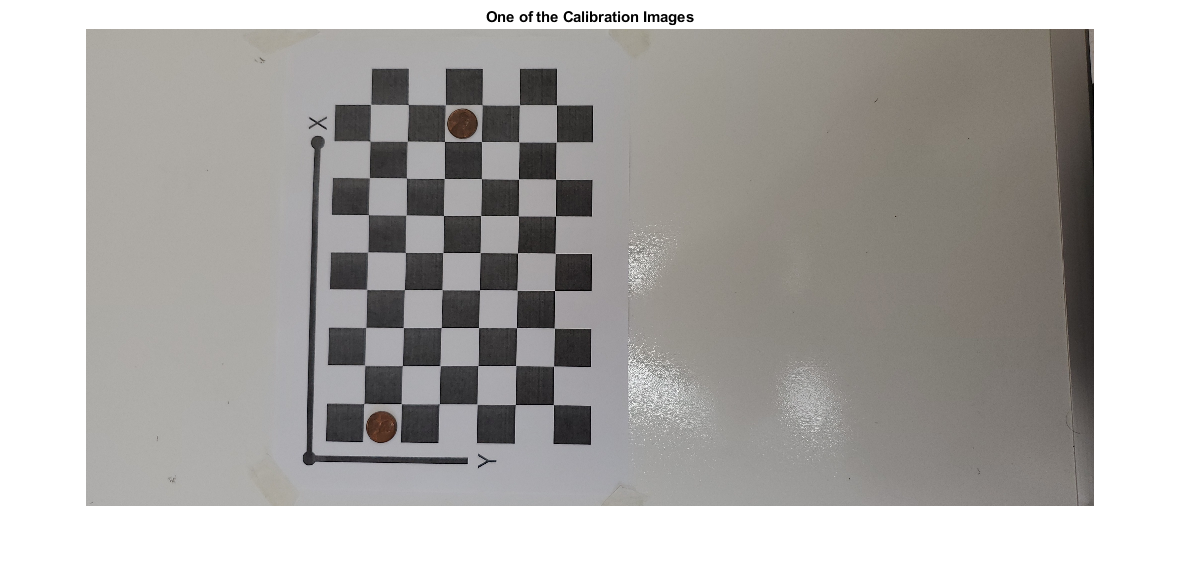

FileToDisplay=1;
magnification = 25;
I = imread(files{FileToDisplay});% show one file
figure; imshow(I, 'InitialMagnification', magnification);
title('One of the Calibration Images');

## Detect features in images

The camera will be described using a projective pinhole camera model with an added two parameter (default) radial distortion correction. The pinhole model assumes a pinhole at a distance *f* from the sensor and above some point near the center of the sensor (optical center). The distance in pixel units and the pixel unit coordinates of the optical center are determined. In a strict simple pinhole camera, if f and the physical pixel size are scaled, holding the pinhole location and camera orientation fixed, the resulting pixellated image is ideally unchanged.

For a compound lens camera system, the effective pinhole is at the front nodal point and f is the distance from the rear principal plane to the sensor.

The first step is to detect and locate the corner points in the pattern. The *detectCheckerboardPoints* function is designed to find and fit corners (L-shapes) after converting an image to greyscale so it is hunting for contrast in intensity. There are four corners in the corner of each square in the pattern. The average of their vertices is used as the location of the checker board corner point. Other algorithms which, for example, fit a grid of straight lines in the linear approximation and curved lines when nonoinearities are postulated, and using all of the image data between corners not just that near corners, would probably be more accurate.

Detect the checkerboard corners in the images. The *detectCheckerboardPoints* function takes one corner quality metric parameter that you can play with. It accepts a list of files and operates on each file in the list so only one call is required. It returns the the pixel numbers of the corner points found, the checkboard board size found, and the list of images used. 

[imagePoints, boardSize,imagesused] = detectCheckerboardPoints(files, 'MinCornerMetric',0.10);

Check if all elements of the logical array i*magesused* are true and halt if not true, else the calibration step will fail. The *all* function does the trick.

if ~all(imagesused)
    fprintf('Oops. No checkerboard found in one or more images. Quitting.'); 
    return
end
imagePointsSave=imagePoints;

## Generate world coordinates of features

Generate the world coordinates of the checkerboard corners in the pattern-centric world coordinate system, with the upper-left corner at (0,0,0), given the number of rows of squares and columns of squares as detected, using the measured square side length in world units (default is mm).

squareSize = 23.02; % measured in millimeters
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

The next step is to fit the set of camera parameters to all of the corner point data, given that in each file the corner points are in a plane. It is assumed that *f* is common to all images. So autofocus should be off and the focus set manually once. The calibration is then valid only for that focus setting. The corner point detector will fail if an image is blurry so you may need to keep the distance between the camera an the center of the pattern fixed as best you can.

## Calibrate the camera

imageSize = [size(I, 1), size(I, 2)];
cameraParams = estimateCameraParameters(imagePoints, worldPoints, ...
        'NumRadialDistortionCoefficients',2','ImageSize', imageSize);

The *estimateCameraParameters* function, given the image points observed and world points of the fixed checkerboard, returns a structure called a *cameraParameters* object. See [https://www.mathworks.com/help/vision/ref/cameraparameters.html](https://www.mathworks.com/help/vision/ref/cameraparameters.html) for a complete description. The object contains the intrinsic parameters of the camera assumed constant (the focal length, optical center coordinates in pixels, and radial distortion parameters) plus, for each image used, the extrinsic parameters (rotation and translation of the camera relative to the pattern), and information about the accuracy of the external parameters deduced from the grand fit.

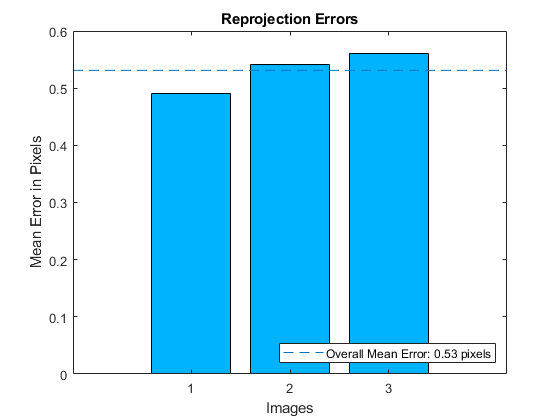

% Evaluate calibration accuracy.
figure; showReprojectionErrors(cameraParams);
title('Reprojection Errors');

The bar graph indicates the accuracy of the calibration. Each bar shows the mean reprojection error for the corresponding calibration image. The reprojection errors are the distances between the corner points detected in the image which have known world coordinates by definition, and the corresponding ideal world points projected from the into the image in the sensor.

Visualize camera extrinsics, i.e. display locations of images relative to the camera or the reverse

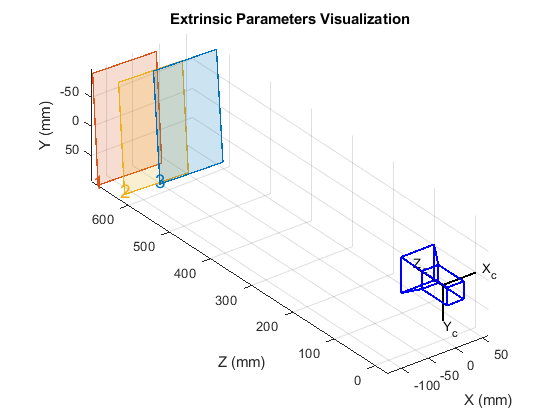

figure;
showExtrinsics(cameraParams);

drawnow;

Plot detected and reprojected points for one file

% figure;
% magnification = 25;
% FileToDisplay=10;
% I = imread(files{FileToDisplay});% show one file
% figure; imshow(I, 'InitialMagnification', magnification);
% title('One of the Calibration Images');
% hold on;
% plot(imagePointsSav(:,1,FileToDisplay),imagePointsSav(:,2,FileToDisplay))
% plot(cameraParams.ReprojectedPoints(:,1,FileToDisplay),...
%     cameraParams.ReprojectedPoints(:,2,FileToDisplay),'r+');
% legend('Detected Points','ReprojectedPoints');
% hold off;

At this point, the cameraparams has all the information about the images used for calibration. If those images contain objects as well as the pattern, one can hunt through the images to find the objects. 

## Read the Image of Objects to Be Measured

Let's assume we take a new fresh image containing the pattern and objects in the plane of the pattern. We will just use one of the images taken and not used in calibration and first find the pattern and extract the external parameters for this image, and then use the same image to find the objects.

Alternatively, you could use two separate images: one containing the pattern, and the other containing the objects to be measured. Again, the objects and the pattern must be in the same plane. Furthermore, images must be captured from exactly the same view point, meaning that the camera must be fixed in place.

Experience indicates that this model and algorithm is prone to fit distortion parameters which are wildly unrealistic outside the grid area. So I recommend finding objects within the grid itself placed so they to not obscure the grid which must be detected in a test image to set the world coordinate system, or placed within the grid area if the 2nd two image strategy is used.

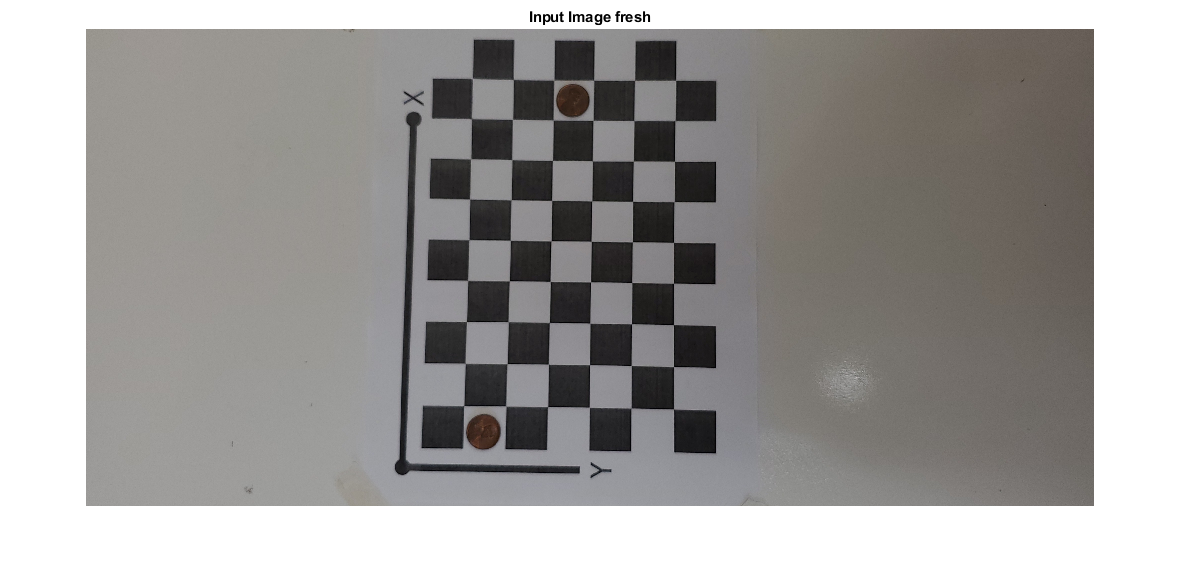

    
imOrig = imread(ObjectsFile);

figure; imshow(imOrig, 'InitialMagnification', magnification);
title('Input Image fresh');

## Undistort the image

Use the cameraParameters object' intrinsic parameters from the calibration step to remove lens distortion from the new image. 

If the lens introduced little distortion, use 'full' output view to illustrate that the image was undistored. If we used the default 'same' option, it would be difficult to notice any difference when compared to the original image. Notice the small black borders.

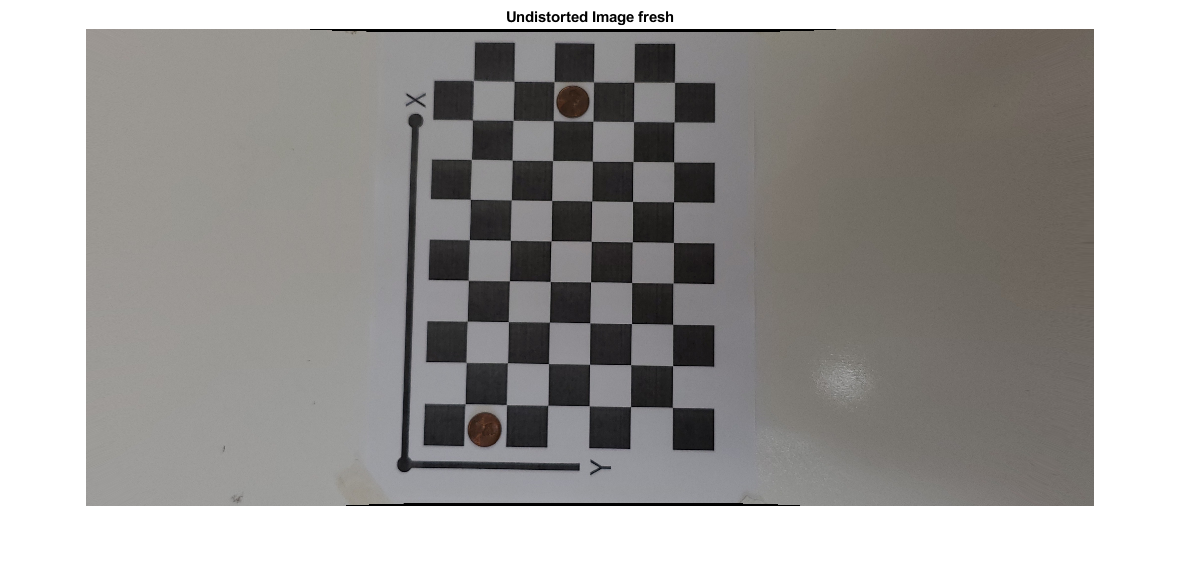

[im, newOrigin] = undistortImage(imOrig, cameraParams, ...
    'OutputView', 'same');
figure; imshow(im, 'InitialMagnification', magnification);
title('Undistorted Image fresh');

## Segment/find objects

Our next step is to find the objects of interest and a variety of techniques could be used such as circleFind in looking for circles. In this case, the coins are colorful on white background. Use the saturation component of the HSV representation of the image to segment them out, the apply blobAnalysis to find connected regions of appropriate area, then use the blob parameters to estimate the radii and and center locations of the appropriate detected blobs.

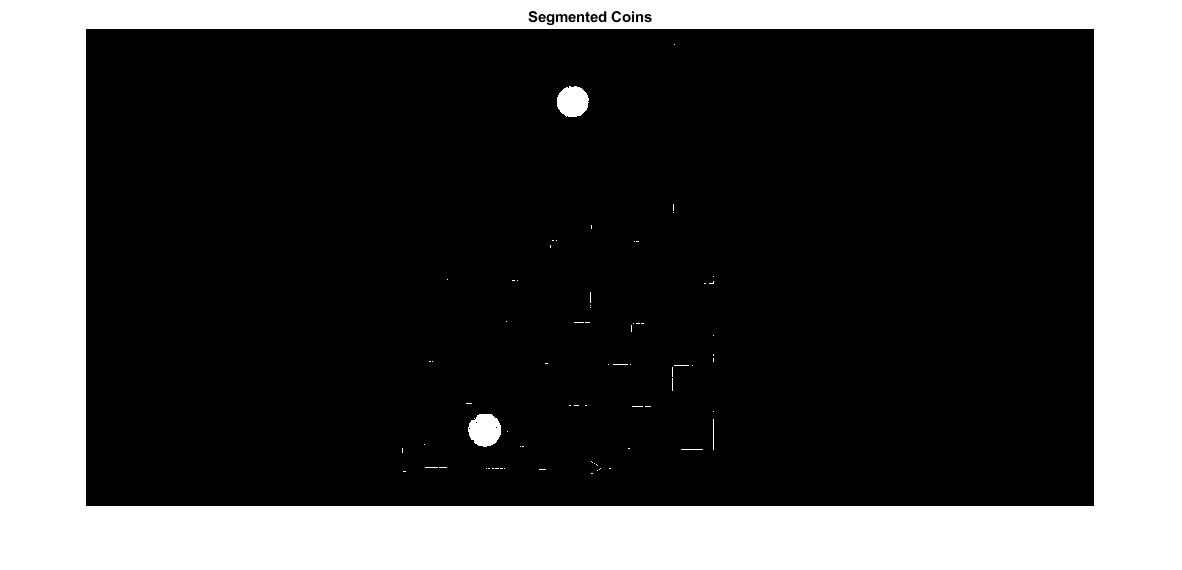

% Convert the image to the HSV color space.
imHSV = rgb2hsv(im);
%image(iMSV)
% Get the saturation channel.
saturation = imHSV(:, :, 2);

% Threshold the image
t = graythresh(saturation)*4.5;
imCoin = (saturation > t);

figure; imshow(imCoin, 'InitialMagnification', magnification);
title('Segmented Coins');

The two coins are quite prominent in this thresholded image.

## Detect objects

We will assume that the two largest connected components in the segmented image correspond to the coins. There are some other structures that were colored and will convert to blobs so one should be careful. these could be distinguished based on blobshape (e.g. eccentricity). To access that information, you will have to turn on appropirate output parameters in the blobAnalysis function call then sift through the blob results yourself. See

[https://www.mathworks.com/help/vision/ref/vision.blobanalysis-system-object.html?searchHighlight=blobanalysis&s_tid=doc_srchtitle](https://www.mathworks.com/help/vision/ref/vision.blobanalysis-system-object.html?searchHighlight=blobanalysis&s_tid=doc_srchtitle) 

and

[https://www.mathworks.com/help/vision/ref/vision.blobanalysis.step.html?searchHighlight=blobanalysis&s_tid=doc_srchtitle](https://www.mathworks.com/help/vision/ref/vision.blobanalysis.step.html?searchHighlight=blobanalysis&s_tid=doc_srchtitle) 

Find connected components. First tell BlobAnalysis what quantities to return. The corresponding parameters have to be set in the exact order BlobAnalysis demands. We want no centroids, bounding boxes, areas.

minarea=1000;% minimum area blob to return
blobAnalysis = vision.BlobAnalysis('AreaOutputPort', true,...
    'CentroidOutputPort', false,...
    'BoundingBoxOutputPort', true,...
    'MinimumBlobArea', minarea, 'ExcludeBorderBlobs', false);

To get eccentricities and an image containing a blob number in every pixel and 0 for pixels not in a blob, adjust the preceding setup call. Next we call the blob analysis object with an input image and collect the areas and boxes requested. If you request more blob information, be sure to receive it by adjusting the following call to step to which advances the blobAnalysis function/object.

[areas, boxes] = step(blobAnalysis, imCoin);


Sort connected components in descending order by area. idx is a list of indices into the list of areas so idx(1) points to the largest area after the sort, i.e. area(idx(1)) will be the largest area

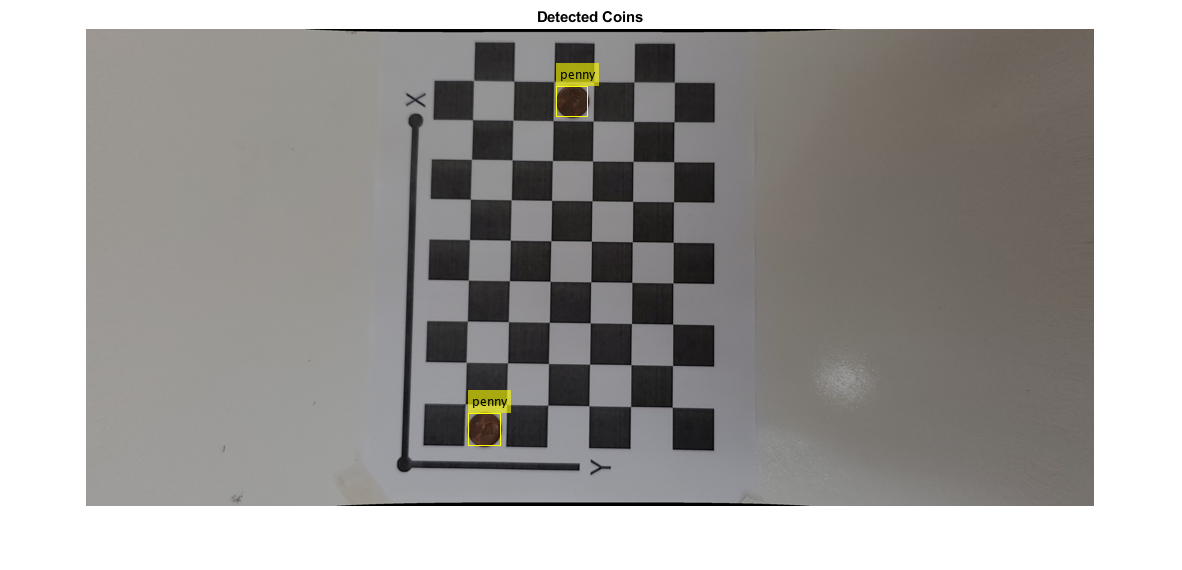

[~, idx] = sort(areas, 'Descend');

% Get the bounding boxes two largest component blobs. 
% Boxes is [x y w h]
boxes = double(boxes(idx(1:2), :));

% Reduce the size of the image for display.
scale = magnification / 100;
imDetectedCoins = imresize(im, scale);

% Insert labels for the coins.
imDetectedCoins = insertObjectAnnotation(imDetectedCoins, 'rectangle', ...
    scale * boxes, 'penny');
figure; imshow(imDetectedCoins);
title('Detected Coins');

## Compute extrinsics for image with objects

To map points in the image coordinates to points in the world coordinates, we need to compute the rotation and the translation of the camera relative to the calibration pattern. Note that the `extrinsics` function assumes that there is no lens distortion. In this case imagePoints have been detected in an image that has already been undistorted using `undistortImage so we have to undistort their values before mapping to world coordinates`.

% Detect the checkerboard in the new image.
[imagePoints, boardSize] = detectCheckerboardPoints(im);

% Adjust the imagePoints so that they are expressed in the coordinate system
% used in the original image, before it was undistorted.  This adjustment
% makes it compatible with the cameraParameters object computed for the original image.
imagePoints = imagePoints + newOrigin; % adds newOrigin to every row of imagePoints

% Compute rotation and translation of the camera. We pass the cameraParams object
% from the calibration step, along with the image and worldPoints defining 
% the world coordinates of the pattern. The extrinsics function will match
% image points to worldpoints given camera instrinsic parameters to
% find the rotation matrix and translation matrix relating camera and
% pattern in this particular image
[R, t] = extrinsics(imagePoints, worldPoints, cameraParams);

## Measure the First Coin

To measure the first coin we convert the top-left and the top-right corners of the bounding box into world coordinates. Then we compute the Euclidean distance between them in millimeters. Note that the actual diameter of a US penny is 19.05 mm. The diameter of a 5c euro is 21.25 mm and the thickness is 1.17 mm. Our results will be sensitive to the algorithm used to measure the object. In the present case, the border of the coin results in a shadow which may get included in the coin shape shifting the position of the center and increasing the apparent diameter.

Adjust upper left corners of bounding boxes for coordinate system shift caused by undistortImage with output view of 'full'. This would not be needed if the output was 'same'. The adjustment makes the points compatible with the cameraParameters of the original image.

boxes = boxes + [newOrigin, 0, 0]; % zero padding is added for widht and height

% Get the top-left and the top-right corners as [x(tl),y(tl);x(tr),y(tr)
box1 = double(boxes(1, :));
imagePoints1 = [box1(1:2); ...
                box1(1) + box1(3), box1(2)];
centerPoints1 = [box1(1)+box1(3)/2,box1(2)+box1(4)/2]

centerPoints1 = 	1.0e+03 *

    1.5950    1.6045


% Get the world coordinates of the corners  and center          
worldPoints1 = pointsToWorld(cameraParams, R, t, imagePoints1);
worldCenter1 = pointsToWorld(cameraParams, R, t, centerPoints1);
% Compute the diameter of the coin in millimeters as width of top b-box.
d = worldPoints1(2, :) - worldPoints1(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf('Measured diameter of one penny = %0.2f mm\n', diameterInMillimeters);

Measured diameter of one penny = 18.14 mm


## Measure the Second Coin

Measure the second coin the same way as the first coin.

% Get the top-left and the top-right corners.
box2 = double(boxes(2, :));
imagePoints2 = [box2(1:2); ...
                box2(1) + box2(3), box2(2)];

centerPoints2 = [box2(1)+box2(3)/2,box2(2)+box2(4)/2]

centerPoints2 = 	1.0e+03 *

    1.9470    0.2915


% Get the world coordinates of the corners  and center          
worldPoints2 = pointsToWorld(cameraParams, R, t, imagePoints2);
worldCenter2 = pointsToWorld(cameraParams, R, t, centerPoints2);
% Compute the diameter of the coin in millimeters.
d = worldPoints2(2, :) - worldPoints2(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf('Measured diameter of the other penny = %0.2f mm\n', diameterInMillimeters);

Measured diameter of the other penny = 18.37 mm


Print locations of centers of two pennies and the difference in world coords

worldCenter1

worldCenter1 =   -14.0728   10.8948


worldCenter2

worldCenter2 =   172.6439   56.8115


We expect the difference in centers of the coins, placed by eye 6 squares apart to be

xpected=[6*squareSize,0]

xpected =   138.1200         0


worldCenter1-worldCenter2

ans =  -186.7167  -45.9167


## Measure the Distance to The First Coin

In addition to measuring the size of the coin, we can also measure how far away it is from the camera. 

% Compute the center of the first coin in the image.
center1_image = box1(1:2) + box1(3:4)/2;

% Convert to world coordinates.
center1_world  = pointsToWorld(cameraParams, R, t, center1_image);

% Remember to add the 0 z-coordinate.
center1_world = [center1_world 0];

% Compute the distance to the camera.
[~, cameraLocation] = extrinsicsToCameraPose(R, t);
distanceToCamera = norm(center1_world - cameraLocation);
fprintf('Distance from the camera to the first penny = %0.2f mm\n', ...
    distanceToCamera);

Distance from the camera to the first penny = 618.27 mm


Same for 2nd coin

% Compute the center of the first coin in the image.
center2_image = box2(1:2) + box2(3:4)/2;

% Convert to world coordinates.
center2_world  = pointsToWorld(cameraParams, R, t, center2_image);

% Remember to add the 0 z-coordinate.
center2_world = [center2_world 0];

% Compute the distance to the camera.
[~, cameraLocation] = extrinsicsToCameraPose(R, t);
distanceToCamera = norm(center2_world - cameraLocation);
fprintf('Distance from the camera to the 2nd penny = %0.2f mm\n', ...
    distanceToCamera);

Distance from the camera to the 2nd penny = 632.87 mm


Let's try an alternate approach use *imfindcircles *rather than the blob finder. See [https://www.mathworks.com/help/images/ref/imfindcircles.html?searchHighlight=circle%20find&s_tid=doc_srchtitle#bta7gun-1-radiusRange](https://www.mathworks.com/help/images/ref/imfindcircles.html?searchHighlight=circle%20find&s_tid=doc_srchtitle#bta7gun-1-radiusRange) .

We will pick a radius range appropriate for our example images and convert pixels to world coordinates then calculate radii

radiusRange=[50,150];% range of radii of circles to look for
%[centers,radii,metric] = imfindcircles(im,radiusRange)
[centers,radii,metric] = imfindcircles(imCoin,radiusRange)

centers = 	1.0e+03 *

    1.9476    0.2901
    1.5957    1.6036


radii =    62.8726
   65.8052


metric =     0.3314
    0.2719


if length(centers)==2
circlecenters = pointsToWorld(cameraParams, R, t, centers)
circleperimeters = pointsToWorld(cameraParams, R, t, centers+radii);
circlediameters=2*(circlecenters-circleperimeters)
end

circlecenters =   172.8433   56.8934
  -13.9436   10.9840


circlediameters =    18.1763  -18.2832
   17.7120  -18.7410


## Summary

This example showed how to use a calibrated camera to measure planar objects. In the MATHWORKS example, the measurements were accurate to within 0.2 mm.

## References

[1] Z. Zhang. A flexible new technique for camera calibration. IEEE Transactions on Pattern Analysis and Machine Intelligence, 22(11):1330-1334, 2000.

[2] Armin Gruen, Thomas S. Huang, Calibration and Orientation of Cameras in Computer Vision. 

Springer Science & Business Media, Mar 9, 2013 

*Copyright 2013-2014 The MathWorks, Inc.*